% PM=importPM('D:\Kw3\罗斯陶的统治者\KstDarkLumon\ProjectMetrics.xlsx','Sheet3');
% for i=3:15
%     for j=2:19
%         PM{i,j}=str2double(split(PM{i,j},' '));
%     end
% end
% 
% ACM=importPM('D:\Kw3\罗斯陶的统治者\KstDarkLumon\AgentClassMetrics.xlsx','Sheet1');

%% Load collected data
load('All.mat');
PM=cell(size(all{1,3},1)+2,size(all,1)+1);
for k=1:size(all,1)
    PM{1,1+k}=string(all{k,1});
    PM{2,1+k}=all{k,2};
end
PM(3:end,1)=all{1,3}.Properties.RowNames;
for k=1:size(all,1)
    for i=1:size(all{1,3},1)
        PM{2+i,1+k}=table2array(all{k,3}(i,:))';
        A=unique(PM{2+i,1+k}(1:4));
        if length(A)==1 && i>=size(all{1,3},1)-1
            PM{2+i,1+k}=A;
        elseif i==4 && table2array(all{k,3}(i,2))>1
            PM{2+i,1+k}=PM{2+i,1+k}/2;
        end
    end
end

ACM=cell(size(all{1,3},1)-2,size(all,1)+1);
ACM(:,1)=all{1,3}.Properties.RowNames(1:end-2);
for k=1:size(all,1)
    if isempty(all{k,5})
        ACM(:,1+k)=table2cell(all{k,4}{1,2});
    else
        ACM(:,1+k)=table2cell(all{k,5});
    end
end

PM(9,:)=[];
ACM(7,:)=[];

% PM_Nom=zeros(18,13);
% for k=3:15
%     tmp=cat(2, PM{k,2:end});
%     tmp=tmp(3,:);
%     tmp=(tmp-min(tmp))./range(tmp);
%     PM_Nom(:,k-2)=tmp';
% end
% boxplot(PM_Nom,);

%% Compare in terms of 12 metrics and scale
unit=[1000,1000,10000,10000,10000,10000,1000,1000,1000,1000,1000,1000,1000];
for k=3:14
    figure;
    DrawBar_OneDim(PM,ACM,k,unit(k-2));
end

%% Compare in terms of 12 metrics
for k=3:14
    figure;
    DrawBar_OneDimS(PM,ACM,k);
end

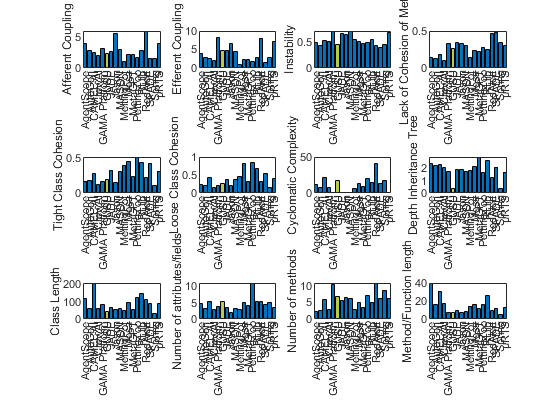

%% Compare in terms of 12 metrics
DrawBar_OneDimS_All(PM,ACM);

%% Show code duplication rate
figure;
DrawBar_Rep(PM);

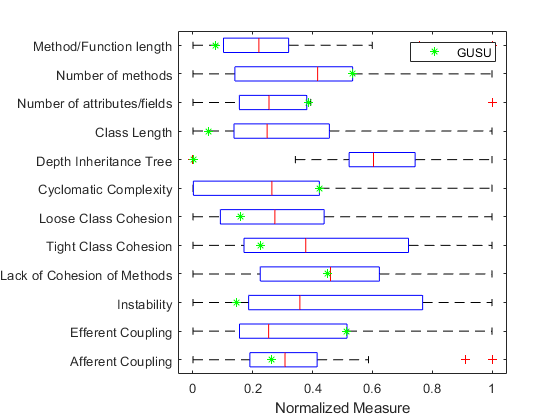

%% BOX diagram, for overall evaluation and agent evaluation
figure;
DrawBox_PM(PM);

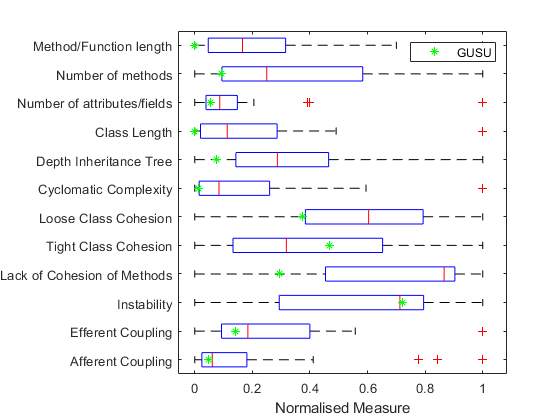

figure;
% subplot(1,2,1);
DrawBox_ACM(ACM);

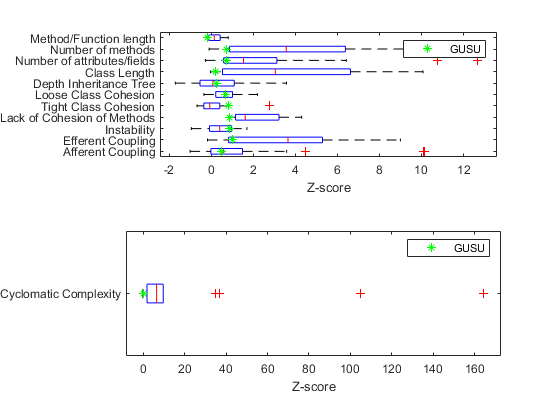

% subplot(1,2,2);
figure;
DrawBox_ZScore(PM,ACM);

%% show the relationship between 12 metrics and LOC
figure;
x=cell2mat(PM(15,2:end));
for k=1:12
    subplot(6,2,k);
    tmp=cat(2, PM{k+2,2:end});
    y=tmp(3,:);
    plot(x,y,'+');
    R=corrcoef(x,y);
    xlabel(strcat(PM{15,1}));
    ylabel(PM{k+2,1});
    text(x(10),y(10),'GUSU');
    title(strcat('R=',num2str(R(1,2))));
end

figure;
for k=1:12
    subplot(6,2,k);
    tmp=cat(1, ACM{k,2:end});
    y=tmp;
    plot(x,y,'+');
    R=corrcoef(x,y);
    xlabel(strcat(PM{15,1}));
    ylabel(PM{k+2,1});
    text(x(10),y(10),'GUSU');
    title(strcat('R=',num2str(R(1,2))));
end

figure;
for k=1:12
    subplot(6,2,k);
    tmp=cat(2, PM{k+2,2:end});
    v=cell2mat(ACM(k,2:end));
    tmp=(v-tmp(3,:))./tmp(5,:);
    y=tmp;
    plot(x,y,'+');
    R=corrcoef(x,y);
    xlabel(strcat(PM{15,1}));
    ylabel(PM{k+2,1});
    text(x(10),y(10),'GUSU');
    title(strcat('R=',num2str(R(1,2))));
end



%% output PM and ACM into excel
PM2=PM';
for i=2:19
    for j=1:2
        PM2{i,j}=char(PM2{i,j});
    end
end
for i=2:19
    for j=3:14
        PM2{i,j}=strcat('max: ',num2str(PM2{i,j}(2),2),...
            ' avg: ',num2str(PM2{i,j}(3),2),...
            ' std: ',num2str(PM2{i,j}(5),2));
    end
    for j=15:16
        PM2{i,j}=num2str(PM2{i,j},2);
    end
end
xlswrite('ProjectMetrics.xlsx',PM2,'sheet1');

ACM2=[PM2(:,1),ACM'];
for i=2:19
    for j=2:13
        ACM2{i,j}=num2str(ACM2{i,j},2);
    end
end
xlswrite('AgentClassMetrics.xlsx',ACM2,'sheet1');

function DrawBar_OneDim(PM,ACM,i,locunit)
tmp=cat(2, PM{i,2:end});
loc=cat(1,PM{16,2:end});
acm=cat(1,ACM{i-2,2:end});
tmp=[tmp(1,:);tmp(5,:);tmp(3,:);tmp(2,:);acm']';%;loc'/locunit
pn=cat(1,PM{1,2:end});
pn2=cat(1,PM{2,2:end});
pn=strcat('_{',pn2,'}',pn);

subplot(1,2,1);
bar(categorical(pn),tmp);
legend('Minimum','Mode','Average','Maximum','Agent Class');
xlabel('Project Name');
ylabel(PM{i,1});

subplot(1,2,2);
tmp=[tmp(:,1:4),acm,loc/locunit];
bar(categorical(pn),tmp);
if locunit==1000
    legend('Minimum','Mode','Average','Maximum','Agent Class','LOC(kloc)');
elseif locunit==10000
    legend('Minimum','Mode','Average','Maximum','Agent Class','LOC(10kloc)');
end
xlabel('Project Name');
ylabel(PM{i,1});
end

function DrawBar_OneDimS(PM,ACM,i)
tmp=cat(2, PM{i,2:end});
acm=cat(1,ACM{i-2,2:end});
pn=cat(1,PM{1,2:end});
pn2=cat(1,PM{2,2:end});
pn=strcat('_{',pn2,'}',pn);

subplot(1,3,1);
bar(categorical(pn),[tmp(3,:);acm']');
legend('Average','Agent Class');
xlabel('Project Name');
ylabel(PM{i,1});

subplot(1,3,2);
bar(categorical(pn),tmp(3,:)');
legend('Average');
xlabel('Project Name');
ylabel(PM{i,1});

subplot(1,3,3);
tmp=[acm];
bar(categorical(pn),tmp);
legend('Agent Class');
xlabel('Project Name');
ylabel(PM{i,1});
end

function DrawBar_OneDimS_All(PM,ACM)
% ind=[3:8;9:14];
% for k=1:2
%     figure;
%     for i=ind(k,:)
%         tmp=cat(2, PM{i,2:end});
%         acm=cat(1,ACM{i-2,2:end});
%         pn=cat(1,PM{1,2:end});
%         pn2=cat(1,PM{2,2:end});
%         pn=strcat('_{',pn2,'}',pn);
        
%         subplot(3,2,i-ind(k,1)+1);
%         b=bar(categorical(pn),tmp(3,:)');
%         b.FaceColor = 'flat';
%         b.CData(6,:)=[0.7,0.8,0.3];
%         hold on;
%         tmp2=tmp(3,:)';
%         tmp2([1:9,11:18],1)=0;
%         bar(categorical(pn),tmp2);
    %     legend('Average');
%         xlabel('Project Name');
%         ylabel(PM{i,1});
%     end
% end

for i=3:14
    tmp=cat(2, PM{i,2:end});
    pn=cat(1,PM{1,2:end});
    
    subplot(3,4,i-2);
    b=bar(categorical(pn),tmp(3,:)');
    b.FaceColor = 'flat';
    b.CData(6,:)=[0.7,0.8,0.3];

    ylabel(PM{i,1});
end
end

function DrawBar_Rep(PM)
tmp=cat(1, PM{16,2:end});
pn=cat(1,PM{1,2:end});
pn2=cat(1,PM{2,2:end});
pn=strcat('_{',pn2,'}',pn);

subplot(1,2,1);
bar(categorical(pn),tmp);
legend('Code Duplication Rate');
xlabel('Project Name');
ylabel(PM{16,1});

subplot(1,2,2);
loc=cat(1,PM{15,2:end});
bar(categorical(pn),loc');
legend('LOC(kloc)');
xlabel('Project Name');
ylabel(PM{15,1});
end

function DrawBox_PM(PM)
data=zeros(18,12);
for k=3:14
    tmp=cat(2, PM{k,2:end});
    tmp=tmp(3,:);
    tmp=(tmp-min(tmp))./range(tmp);
    data(:,k-2)=tmp';
end
% pn=cat(1,PM{1,2:end});
% pn2=cat(1,PM{2,2:end});
% pn=strcat('_{',pn2,'}',pn);
pn=PM(3:14,1);
boxplot(data,pn,'Orientation','horizontal','Whisker',1.8);%,'LabelOrientation','inline'
hold on
plot(data(10,:),1:12,'*g');
legend('GUSU');
xlabel('Normalized Measure');
hold off
end

function DrawBox_ACM(ACM)
data=zeros(18,12);
for k=1:12
    tmp=cat(1, ACM{k,2:end});
    tmp=(tmp-min(tmp))./range(tmp);
    data(:,k)=tmp';
end
% pn=cat(1,PM{1,2:end});
% pn2=cat(1,PM{2,2:end});
% pn=strcat('_{',pn2,'}',pn);
pn=ACM(1:12,1);
boxplot(data,pn,'Orientation','horizontal','Whisker',1.8);%,'LabelOrientation','inline'
hold on
plot(data(10,:),1:12,'*g');
legend('GUSU');
xlabel('Normalised Measure');
hold off
end

function DrawBox_ZScore(PM,ACM)
data=zeros(18,12);
ind=[1:6,8:12];
for k=1:12
    tmp=cat(2, PM{k+2,2:end});
    v=cell2mat(ACM(k,2:end));
    tmp=(v-tmp(3,:))./tmp(5,:);
%     if k==7
%         tmp=log(tmp);
%     end
    data(:,k)=tmp';
end
pn=ACM(1:12,1);

subplot(2,1,1);
% subplot('Position',[0.1,0.4,0.8,0.4])
boxplot(data(:,ind),pn(ind),'Orientation','horizontal','Whisker',1.8);%,'LabelOrientation','inline'
hold on
plot(data(10,ind),1:11,'*g');
legend('GUSU');
xlabel('Z-score');
hold off

subplot(2,1,2);
% subplot('Position',[0.1,0,0.8,0.1])
boxplot(data(:,7),pn(7),'Orientation','horizontal','Whisker',1.8);
hold on
plot(data(10,7),1,'*g');
legend('GUSU');
xlabel('Z-score');
hold off
end

function data = importPM(workbookFile, sheetName, range)
%IMPORTFILE 导入电子表格中的数据
%   DATA = IMPORTFILE(FILE) 读取名为 FILE 的 Microsoft Excel
%   电子表格文件的第一张工作表中的数据，并以元胞数组的形式返回该数据。
%
%   DATA = IMPORTFILE(FILE,SHEET) 从指定的工作表中读取。
%
%   DATA = IMPORTFILE(FILE,SHEET,RANGE) 从指定的工作表和指定的范围中读取。使用语法 'C1:C2'
%   指定范围，其中 C1 和 C2 是区域的对角。%
% 示例:
%   ProjectMetrics = importfile('ProjectMetrics.xlsx','Sheet3','A1:S17');
%
%   另请参阅 XLSREAD。

% 由 MATLAB 自动生成于 2026/06/28 13:31:35

%% 输入处理

% 如果未指定工作表，则将读取第一张工作表
if nargin == 1 || isempty(sheetName)
    sheetName = 1;
end

% 如果未指定范围，则将读取所有数据
if nargin <= 2 || isempty(range)
    range = '';
end

%% 导入数据
[~, ~, data] = xlsread(workbookFile, sheetName, range);
data(cellfun(@(x) ~isempty(x) && isnumeric(x) && isnan(x),data)) = {''};

idx = cellfun(@ischar, data);
data(idx) = cellfun(@(x) string(x), data(idx), 'UniformOutput', false);

end

